clc 
%clear
%relerr = zeros([6, 1]);
%err = zeros([6 1]);
%semilogy(20:10:90, err)

`Richardson Extrapolation`

I still need to estimate $p$. For that we need to calculate $Q(u_h)$ and $Q(u_{h/2})$ for some $h=\frac{1}{I}$ for some $I$.

%l = 4;
N = 10;
I = 100;
h = 1/I;
I_2 = 2*I;
h2 = 1/(2*I);

Now we sample the random field $a(x,w)$ $M$ times for model 2 and $\nu=0.5$. The initial variables we need are

M = 10^3;
nu = 1.5;
x = linspace(0, 1, I+1);
x_h2 = linspace(0, 1, I_2 + 1);
x_half = zeros([I+1 1]);
x_half_h2 = zeros([I_2+1 1]);
for k=1:I
    x_half(k) = (x(k+1) + x(k))/2;
end

for k=1:I_2
    x_half_h2(k) = (x_h2(k+1) + x_h2(k))/2;
end

First we precalculate the correpsonding covariance matrix and singular values.

C = Matern_specialcases_only(x_half, nu);
[EVec, EVal] = eig(C);
SV = zeros([I 1]);
EVec = flip(EVec, 2);
for k=1:I
    SV(k) = sqrt(EVal(I+1-k, I+1-k));
end

C_h2 = Matern_specialcases_only(x_half_h2, nu);
[EVec_h2, EVal_h2] = eig(C_h2);
SV_h2 = zeros([I_2 1]);
EVec_h2 = flip(EVec_h2, 2);
for k=1:I_2
    SV_h2(k) = sqrt(EVal_h2(I_2+1-k, I_2+1-k));
end

Now we calculate $M$ realisations of the random field $a(x,w)$

% Generate random samples from std Gaussian
rng(1)
x_hat = linspace(0, 1, N + 1);
Y = normrnd(0, 1, [N M]);
a = zeros([M I+1]);
a_h2 = zeros([M I_2+1]);

for sample=progress(1:M)
    ind = zeros([length(x) N]);
    ind_h2 = zeros([length(x_h2) N]);
    % Calculate for every node in the I mesh
    for l=1:length(x)
        % Check for every node in I mesh if its in [x^(k-1), x^(k)]
        for r=2:N+1
            if (x(l) >= x_hat(r-1) & x(l) <= x_hat(r))
                ind(l, r-1) = Y(r-1, sample);
            else
                ind(l, r-1) = 0;
            end
        end
    end
    for l=1:length(x_h2)
        % Check for every node in I mesh if its in [x^(k-1), x^(k)]
        for r=2:N+1
            if (x_h2(l) >= x_hat(r-1) & x_h2(l) <= x_hat(r))
                ind_h2(l, r-1) = Y(r-1, sample);
            else
                ind_h2(l, r-1) = 0;
            end
        end
    end
    stairs = crop(ind);
    stairs_h2 = crop(ind_h2);
            

    a(sample, :) = 1 + 0.5*stairs;
    a_h2(sample, :) = 1 + 0.5*stairs_h2;
end

Processing:  000%  |                                    | 0/1000it [00:00:00<Inf:NaN:NaN, Inf it/s]


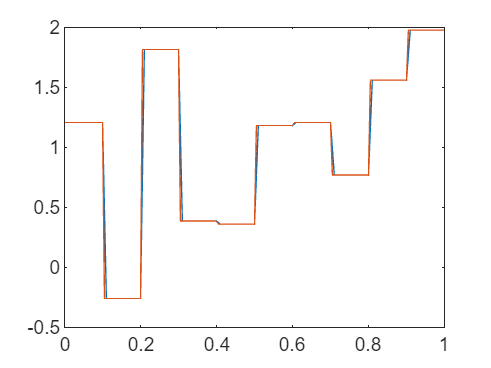



%{
for sample=progress(1:M)
    inner = zeros([I+1 N]);
    inner_h2 = zeros([I_2+1 N]);
    for k=1:N
        inner(:, k) = SV(k)*Y(k, sample).*EVec(:, k);
        inner_h2(:, k) = SV_h2(k)*Y(k, sample).*EVec_h2(:, k);
    end

    kappa = sum(inner, 2);
    a(sample, :) = exp(kappa);

    kappa_h2 = sum(inner_h2, 2);
    a_h2(sample, :) = exp(kappa_h2);
end
%}


for i=1:M
    plot(x, a(i, :), x_h2, a_h2(i, :))
end

Using these realisations we can now approximate the solution $u$ of the PDE by $u_h$

F = zeros([I+1 1]);
for i=1:I+1
    F(i) = 4*pi^2*cos(2*pi*x_half(i));
end

F_h2 = zeros([I_2+1 1]);
for i=1:I_2+1
    F_h2(i) = 4*pi^2*cos(2*pi*x_half_h2(i));
end

u_h = zeros([M I+1]);
u_h2 = zeros([M I_2+1]);
for sample=progress(1:M)
    A = zeros([I+1 I+1]);
    A_h2 = zeros([I_2+1 I_2+1]);
    for i=2:I
       A(i, i-1) = -a(sample, i-1)/(h^2);
       A(i, i) = (a(sample, i-1) + a(sample, i+1))/(h^2);
       A(i, i+1) = -a(sample, i+1)/(h^2);
    end

    for i=2:I_2
       A_h2(i, i-1) = -a_h2(sample, i-1)/(h2^2);
       A_h2(i, i) = (a_h2(sample, i-1) + a_h2(sample, i+1))/(h2^2);
       A_h2(i, i+1) = -a_h2(sample, i+1)/(h2^2);
    end

    u_h(sample, :) = A(2:I, :)\F(2:I);
    u_h2(sample, :) = A_h2(2:I_2, :)\F_h2(2:I_2);
end

Processing:  000%  |                                    | 0/1000it [00:00:00<Inf:NaN:NaN, Inf it/s]


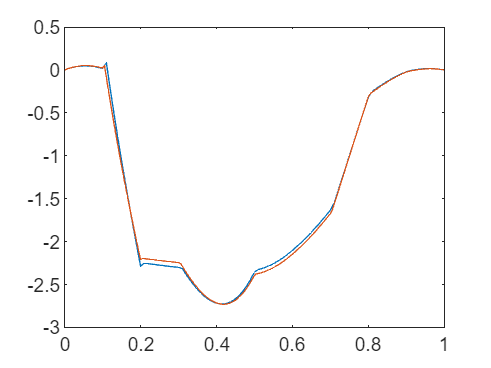


for i=1:M
    plot(x, u_h(i, :), x_h2, u_h2(i, :))

end


u_h(1, :)

ans =          0    0.0605    0.1151    0.1640    0.2072    0.2448    0.2769    0.3036    0.3251    0.3415    0.3532    0.3562    0.3556    0.3532    0.3492    0.3437    0.3368    0.3286    0.3193    0.3090    0.2979    0.2676    0.1887    0.1087    0.0281   -0.0526   -0.1332   -0.2132   -0.2921   -0.3697   -0.4455   -0.5482   -0.6879   -0.8236   -0.9547   -1.0809   -1.2016   -1.3165   -1.4251   -1.5271   -1.6220   -1.6896   -1.7358   -1.7759   -1.8098   -1.8372   -1.8580   -1.8722   -1.8796   -1.8802


Now we can get the Quantities of Interest

QuantOfInt = zeros([M 1]);
QuantOfInt_h2 = zeros([M 1]);
for sample=1:M
    QuantOfInt(sample) = h*sum(u_h(sample, :));
    QuantOfInt_h2(sample) = h2*sum(u_h2(sample, :));
end

And thus calculate a Monte Carlo estimate

MC_est_h = 1/M*sum(QuantOfInt)

MC_est_h = -3.8402

MC_est_h2 = 1/M*sum(QuantOfInt_h2)

MC_est_h2 = -3.9575

%relerr(9) = abs(MC_est_h - MC_est_h2)/abs(MC_est_h2)

%err(9) = abs(MC_est_h - MC_est_h2)/abs(MC_est_h2)

MC_h = zeros([1 M]);
MC_h2 = zeros([1 M]);
for i=1:M
    MC_h(i) = 1/i*sum(QuantOfInt(1:i));
    MC_h2(i) = 1/i*sum(QuantOfInt_h2(1:i));
end

Now we plot and fit

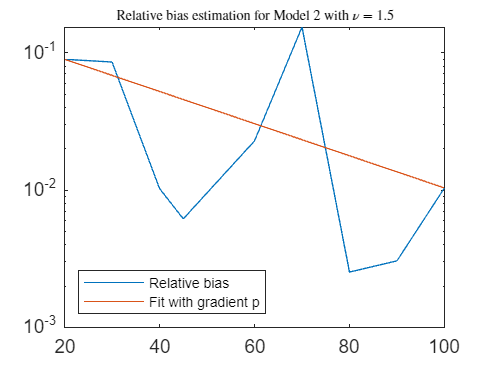

semilogy([20 30 40 45 60 70 80 90 100], err, [20 100], [err(1) err(end)])
title("Relative bias estimation for Model 2 with $\nu=1.5$", "Interpreter", "latex", fontsize=7)
legend("Relative bias", "Fit with gradient p", fontsize=7, location="southwest")

((err(end) - err(1))/(1/100- 1/20))

ans = 1.9803

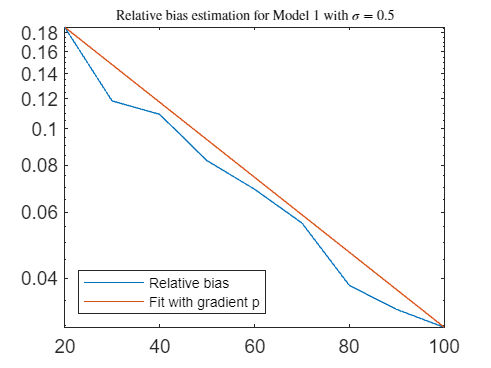

%savePDF("C:/git/UQ4PDE_Homeworks/Homework 1/Plots/Part 2/", "p_est_nu15")
semilogy([20 30 40 50 60 70 80 90 100], relerr, [20 100], [relerr(1) relerr(end)])
title("Relative bias estimation for Model 1 with $\sigma=0.5$", "Interpreter", "latex", fontsize=7)
legend("Relative bias", "Fit with gradient p", fontsize=7, location="southwest")

((relerr(end) - relerr(1))/(1/100- 1/20))

ans = 3.9181

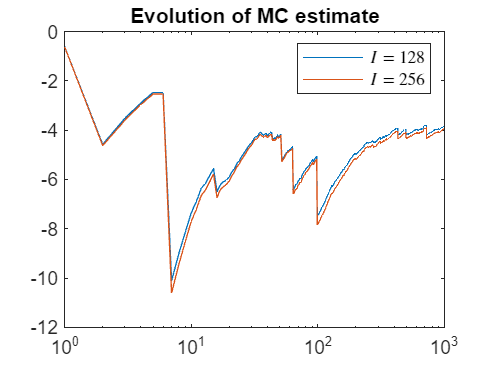

%savePDF("C:/git/UQ4PDE_Homeworks/Homework 1/Plots/Part 2/", "p_est_nu15")


semilogx(1:M, MC_h, 1:M, MC_h2)
title("Evolution of MC estimate")
legend("$I=128$", "$I=256$", "Interpreter", "latex")